# One Patient

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

clearvars; clc;
patients = find_patients('eeg');
patient = patients{1};

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:ah7



info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.classes=[info.cue_BH,info.cue_BF]';
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;
info.num_channels = 16;
info.selected_frequencies = (4:2:96)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

## EEG data

EEG_data = cell(size(patient.offline_files));
for file_i = 1:length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{file_i});
    EEG_data{file_i}.data = s(:,1:info.num_channels);
    EEG_data{file_i}.EVENT = standardize_event(h.EVENT);
    % We assume all frequencies to be the same for all data.
    info.sample_rate = h.SampleRate;
end

## concatenate data

[eeg,EVENT,run_k]=concatenate_chunks(EEG_data);

## label the data

[cue_k, trial_k] = labelData(EVENT,length(eeg));

# Power spectrum

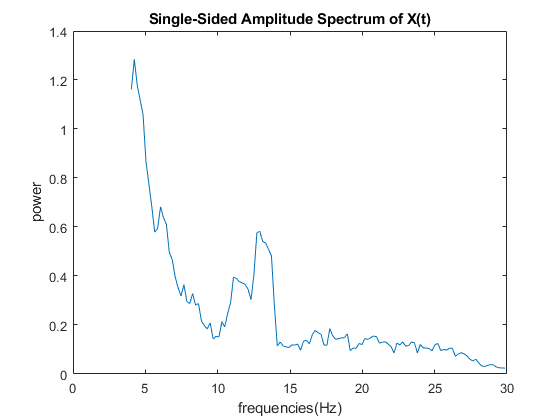

selected_trial = 5;
[power_spectrum,frequencies_axis] = single_side_power_spectrum(eeg, trial_k, selected_trial, info.sample_rate, [4 30]);

figure;
plot(frequencies_axis,power_spectrum) ;
title('Single-Sided Amplitude Spectrum of X(t)');
xlabel('frequencies(Hz)');
ylabel('power');

# ERD and ERS logarithmic band power

## EEG filtering

filtOrder = 4;
band_mu   = [8 12];
band_beta = [18 22]; 

% Filter parameters
[b_mu, a_mu]     = butter(filtOrder, band_mu*2/info.sample_rate);
[b_beta, a_beta] = butter(filtOrder, band_beta*2/info.sample_rate);


% Applying filters
mu_filtered_eeg   = zeros(size(eeg));
beta_filtered_eeg = zeros(size(eeg));

for channel_i = 1:info.num_channels
    mu_filtered_eeg(:, channel_i) = filtfilt(b_mu, a_mu, eeg(:, channel_i));
    beta_filtered_eeg(:, channel_i) = filtfilt(b_beta, a_beta, eeg(:, channel_i));
end


## Squaring

squaring is a way to rectify the signal

rect_mu_eeg = power(mu_filtered_eeg, 2);
rect_beta_eeg = power(beta_filtered_eeg, 2);

## Moving average

moving_avg_mu_eeg   = zeros(size(eeg));
moving_avg_beta_eeg = zeros(size(eeg));
% [seconds] smoothing window length to compute power
window    = 1;                                 
for channel_i = 1:info.num_channels
    moving_avg_mu_eeg(:, channel_i)   = (filter(ones(1, window*info.sample_rate)/window/info.sample_rate, 1, rect_mu_eeg(:, channel_i)));
    moving_avg_beta_eeg(:, channel_i) = (filter(ones(1, window*info.sample_rate)/window/info.sample_rate, 1, rect_beta_eeg(:, channel_i)));
end

## Logarithmic transformation

log_power_mu   = log(moving_avg_mu_eeg);
log_power_beta = log(moving_avg_beta_eeg);

## Trial extraction

Extracting data for each trial (be careful that length might be different for few sample)

we consider the trial from the start of the cue event to the end of the continuos feedback

[trial_mu_data, trial_run_k, trial_cue_k] = extract_trials(log_power_mu, cue_k~=0, trial_k, cue_k, run_k);
trial_beta_data = extract_trials(log_power_beta, cue_k~=0, trial_k, cue_k, run_k);

## Visualization ERS and ERD

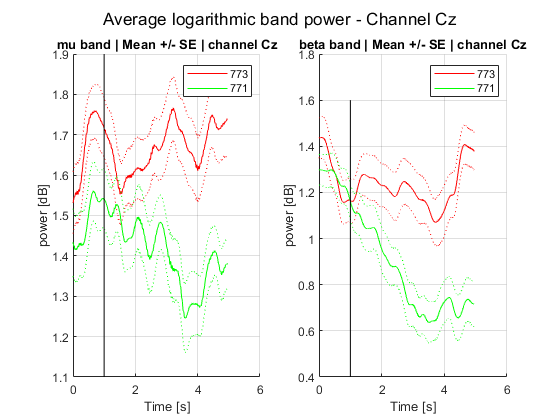

selected_channel = 9; %c3
num_points = size(trial_mu_data,1);
num_trials = length(nonzeros(unique(trial_k)));

all_trials_power_mu = squeeze(trial_mu_data(:, selected_channel, :));
all_trials_power_beta = squeeze(trial_beta_data(:, selected_channel, :));

x_axis = linspace( 0, num_points/info.sample_rate, num_points);
figure;
subplot(1, 2, 1);
visualize_ERD(x_axis, all_trials_power_mu, info.classes, num_trials ,trial_cue_k);
title(['mu band | Mean +/- SE | channel ' info.channel_labels{selected_channel}]);

subplot(1, 2, 2);
visualize_ERD(x_axis, all_trials_power_beta, info.classes, num_trials ,trial_cue_k);
title(['beta band | Mean +/- SE | channel ' info.channel_labels{selected_channel}]);

sgtitle(['Average logarithmic band power - Channel ' info.channel_labels{selected_channel}]);

# ERD-ERS Power spectral density

## EEG -> PSD

PSD_data = cell(1)%size(patient.offline_files));
for file_i = 1:1%length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{file_i});

PSD_data = 1×1 cell array
    {0×0 double}


    data = psd_extraction(s,h);
    PSD_data{file_i}.data = data.PSD;
     PSD_data{file_i}.EVENT = data.EVENT;
    % We assume all frequencies to be the same for all data.
    info.frequencies = data.frequencies;
end


[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


## concatenate PSD

[PSD,EVENT,run_k] = concatenate_chunks(PSD_data);

## label data

[cue_k,trial_k]=labelData(EVENT,length(PSD));

## extract frequencies

[PSD, info.frequencies] = extractFrequencies(PSD, info.frequencies, info.selected_frequencies);

## Data information


NWindows  = size(PSD, 1);
NFreqs    = size(PSD, 2);
NChannels = size(PSD, 3);
mlength    = 1;
wlength    = 0.5;
pshift     = 0.25;                  
wshift     = 0.0625;  
winconv = 'backward'; 
nclasses = length(info.classes);

%% Creating vector labels
CFeedbackPOS = EVENT.POS(EVENT.TYP == 781);
CFeedbackDUR = EVENT.DUR(EVENT.TYP == 781);

CuePOS = EVENT.POS(EVENT.TYP == 771 | EVENT.TYP == 773);
CueDUR = EVENT.DUR(EVENT.TYP == 771 | EVENT.TYP == 773);
CueTYP = EVENT.TYP(EVENT.TYP == 771 | EVENT.TYP == 773);

FixPOS = EVENT.POS(EVENT.TYP == 786);
FixDUR = EVENT.DUR(EVENT.TYP == 786);
FixTYP = EVENT.TYP(EVENT.TYP == 786);

NumTrials = length(CFeedbackPOS);

% We consider the intersting period from Cue apperance to end of continuous feedback
Ck = zeros(NWindows, 1);
Tk = zeros(NWindows, 1);
TrialStart = nan(NumTrials, 1);
TrialStop  = nan(NumTrials, 1);
FixStart = nan(NumTrials, 1);
FixStop  = nan(NumTrials, 1);
for trId = 1:NumTrials
    cstart = CuePOS(trId);
    cstop  = CFeedbackPOS(trId) + CFeedbackDUR(trId) - 1;
    Ck(cstart:cstop) = CueTYP(trId);
    Tk(cstart:cstop) = trId;
    
    TrialStart(trId) = cstart;
    TrialStop(trId)  = cstop;
    FixStart(trId)   = FixPOS(trId);
    FixStop(trId)    = FixPOS(trId) + FixDUR(trId) - 1;
end

%% Trial extraction

% Extracting data for each trial (be careful that length might be different for few sample)
disp('[proc] + Extracting data for each trial');

[proc] + Extracting data for each trial


MinTrialDur = min(TrialStop - TrialStart);
TrialData   = nan(MinTrialDur, NFreqs, NChannels, NumTrials);
tCk = zeros(NumTrials, 1);
for trId = 1:NumTrials
    cstart = TrialStart(trId);
    cstop  = cstart + MinTrialDur - 1;
    TrialData(:, :, :, trId)   = PSD(cstart:cstop, :, :);
   
    tCk(trId) = unique(Ck(cstart:cstop));
end

%% Baseline extraction (from fixation)
disp('[proc] + Extracting baseline data for each trial');

[proc] + Extracting baseline data for each trial


MinFixDur = min(FixStop - FixStart);
FixData   = nan(MinFixDur, NFreqs, NChannels, NumTrials);

for trId = 1:NumTrials
    cstart = FixStart(trId);
    cstop  = cstart + MinFixDur - 1;
    FixData(:, :, :, trId)   = PSD(cstart:cstop, :, :);
end

%% ERD/ERS
disp('[proc] + Computing ERD/ERS');

[proc] + Computing ERD/ERS


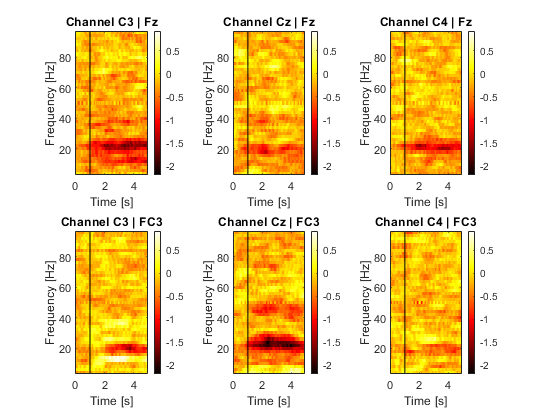


% Average and replicate the value of the baseline
Baseline = repmat(mean(FixData), [size(TrialData, 1) 1 1 1]);
ERD = log(TrialData./ Baseline);

%% Visualization 1
figure;
t = linspace(0, MinTrialDur*wshift, MinTrialDur);
ChannelSelected = [7 9 11]; 

chandles = [];
for cId = 1:nclasses
    
    climits = nan(2, length(ChannelSelected));
    for chId = 1:length(ChannelSelected)
        subplot(2, 3, (cId - 1)*length(ChannelSelected) + chId);
        cdata = mean(ERD(:, :, ChannelSelected(chId), tCk == info.classes(cId)), 4);
        imagesc(t, info.frequencies, cdata');
        set(gca,'YDir','normal');
        climits(:, chId) = get(gca, 'CLim');
        chandles = cat(1, chandles, gca);
        colormap(hot);
        colorbar;
        title(['Channel ' info.channel_labels{ChannelSelected(chId)} ' | ' info.channel_labels{cId}]);
        xlabel('Time [s]');
        ylabel('Frequency [Hz]');
        line([1 1],get(gca,'YLim'),'Color',[0 0 0])
    end
    
end
set(chandles, 'CLim', [min(min(climits)) max(max(climits))]);

function [power_spectrum,frequencies_axis] = single_side_power_spectrum(eeg, trial_k, selected_trial, sample_rate, band)

X=eeg(trial_k==selected_trial, :);
num_points = length(X);
%we need even number of points
if rem(num_points, 2) ~= 0
    num_points= num_points-1;
    X = X(1:num_points,:);
end
frequence_step = sample_rate/num_points;
points_per_Hz = 1/frequence_step;
fourier_transform = fft(X,num_points);

P2 = abs(fourier_transform./num_points).^2;
P1 = P2(1:num_points/2+1,:);
P1(2:end-1,:) = 2*P1(2:end-1,:);

frequencies_axis = frequence_step*(0:(num_points/2));

% mean over all channels
m=mean(P1,2);

%moving average
window_length = 1.5;% Hz for windows
window = floor(window_length*points_per_Hz);
m = filter(ones(1, window)/window, 1, m);

%select band
index = frequencies_axis >= band(1) & frequencies_axis <= band(2);
frequencies_axis = frequencies_axis(index);
power_spectrum = m(index);
end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function visualize_ERD(x_axis, all_trials_power, classes, num_trials ,cue_k_trialbased)
% signal [windows x trials]

num_classes = length(classes);
colors = {'r', 'g', 'b'};
colors = colors(1:num_classes);
plotted_signals = nan(num_classes, 1);

for class_i = 1:num_classes
    hold on;
    index = (cue_k_trialbased == classes(class_i));
    signal = all_trials_power(:, index);
    average_signal = mean(signal, 2);
    standard_error = std(signal/sqrt(num_trials/2), [], 2);
    plotted_signals(class_i) = plot(x_axis, average_signal, colors{class_i});
    plot(x_axis, average_signal + standard_error, [colors{class_i} ':']);
    plot(x_axis, average_signal - standard_error, [colors{class_i} ':']);
    hold off;
end
xlabel('Time [s]');
ylabel('power [dB]');
line([1 1],get(gca,'YLim'),'Color',[0 0 0])
grid on;
legend(plotted_signals, num2str(classes));
end